# Biomedical Signal & Image Processing

**Session 8**

@Autors 

Roham Kaveie - Ehsan Merikhi

## Question 1

We create a 4x4 square kernel in the center of a new binary image, multiply it in the Fourier domain by the Fourier transform of the original image, convert it back to the spatial domain, and plot the result alongside the original and noisy versions.

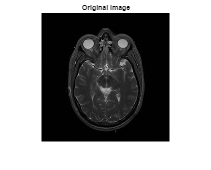

clc;clear;
img = imread('Lab 8_data/S2_Q1_utils/t2.jpg');
first_slice = img(:,:,1);

%% add noise 
variance = 15;
mean = 0;
sigma = sqrt(variance);
noisy_image = double(first_slice) + normrnd(mean, sigma, size(first_slice));
noisy_image = uint8(min(max(noisy_image, 0), 255)); % Ensure pixel values are valid

% create a 4x4 Square Kernel (Normalized)
kernel_size = 4;
kernel = ones(kernel_size) / (kernel_size^2); % Normalized kernel

original_fft = fft2(double(first_slice));
kernel_fft = fft2(kernel, size(first_slice, 1), size(first_slice, 2)); % zero-padding to match image size

% multiply in the Fourier domain
result_fft = original_fft .* kernel_fft;
result_image = abs(ifft2(result_fft));

sigma_gaussian = 1;
convolved_image = imgaussfilt(first_slice, sigma_gaussian);

% Step 6: Plotting the Results
figure;
figure;
imshow(first_slice);
title('Original Image');

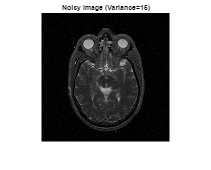


figure;
imshow(noisy_image);
title('Noisy Image (Variance=15)');

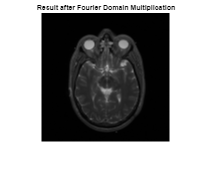


figure;
imshow(uint8(result_image));
title('Result after Fourier Domain Multiplication');

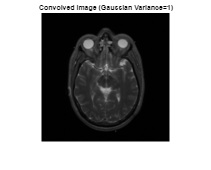


% Compare with Gaussian Convolution Result
figure;
imshow(convolved_image);
title('Convolved Image (Gaussian Variance=1)');


figure;
imshow(uint8(result_image));
title('Result after Fourier Domain Multiplication');

## Question 2

To blur the original image, we first create a 4x4 kernel, then calculate the Fourier transform of the image and the kernel, multiply them together, and take the inverse Fourier transform to obtain the blurred image. To restore the original image, it is enough to divide the Fourier transform of the blurred image by the Fourier transform of the kernel, so that the original image is restored after the inverse Fourier transform.

Then We repeat all of this again, except that before restoring the original image, we add some Gaussian noise to the blurred image.

clear; clc;
img = imread('Lab 8_data/S2_Q1_utils/t2.jpg');
first_slice = img(:,:,1);

sigma_gaussian = 0.5;
gaussian_kernel = gaussianKernel([21 21],sigma_gaussian);

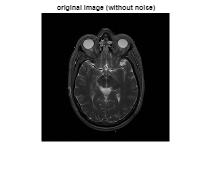

%gaussian_kernel = gaussian_kernel/sum(gaussian_kernel)

original_fft = fft2(double(first_slice));
kernel_fft = fft2(gaussian_kernel, size(first_slice, 1), size(first_slice, 2)); % zero-padding to match image size


% multiply in the Fourier domain
filtered_fft = original_fft .* kernel_fft;
filtered_image = abs(ifft2(filtered_fft));
filtered_image = filtered_image/max(max(filtered_image));

recovered_fft = filtered_fft ./kernel_fft;
recovered_image = abs(ifft2(recovered_fft));
recovered_image = recovered_image/max(max(recovered_image));

figure;
imshow(first_slice);
title('original image (without noise)')

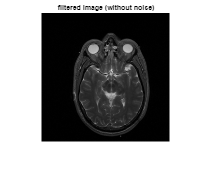

figure
imshow(filtered_image);
title('filtered image (without noise)')

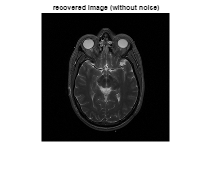

figure;
imshow(recovered_image);
title('recovered image (without noise)')

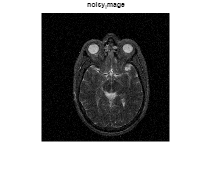

% add noise to gaussain filtered image

%% add noise 
variance = 0.001;
mean = 0;
sigma = sqrt(variance);
noise = normrnd(mean, sigma, size(first_slice));
noisy_image = double(filtered_image) + noise;
%noisy_image = uint8(min(max(noisy_image, 0), 255)); % Ensure pixel values are valid
noisy_fft = fft2(double(noisy_image));


recovered_fft = noisy_fft ./kernel_fft;
recovered_image = abs(ifft2(recovered_fft));
recovered_image = recovered_image/max(max(recovered_image));

figure;
imshow(noisy_image);
title('noisy_image')

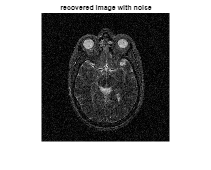


figure;
imshow(recovered_image);
title('recovered image with noise')

## Question 3

First, we create a 3x3 Gaussian matrix D from a 3x3 Gaussian kernel and blur it by multiplying it with the original image and then add a Gaussian noise to it. Finally, using the pinv function, we find the closest matrix to the inverse matrix D and multiply it with the blurred image to restore the original image. It can be seen that the image is not restored well and the effect of noise is evident in it and even if we increase the noise variance, the image is not restored correctly at all.

clear all; clc;
Img = imread("Lab 8_data\S2_Q3_utils\t2.jpg");
fisrt_slide = Img(:,:,1);
img = double(fisrt_slide);
% Resize the image to 64x64
img = imresize(img, [64, 64]);
num_row = size(img,1);
num_col = size(img,2);

h = [0,1,0;1,2,1;0,1,0];
K = zeros(size(img));
K(1:3,1:3) = h;

D = zeros(num_col*num_col,num_col*num_col); 

for r = 1:num_row
    for c = 1:num_col

        shiffted_kernel = circshift(K,r-1,1);
        shiffted_kernel = circshift(shiffted_kernel,c-1,2);
        D((r-1)*num_col+c,:) = shiffted_kernel(:);
    end
end

g = D*img(:);
g = g + normrnd(0,0.3,size(g));

f_hat = pinv(D) * g;
f_hat = reshape(f_hat, num_col, num_col);
f_hat = f_hat/max(f_hat(:));

figure;
subplot(1,3,1);
imshow(img/max(img(:)))
title('original image')
subplot(1,3,2);
noisy_image  = reshape(g,num_col,num_col);
noisy_image = noisy_image/max(noisy_image(:));
imshow(noisy_image);
title('gaussian filtered image with noise')
subplot(1,3,3);
imshow(f_hat);
title('recovered image')


ans =         4096           1


ans =         4096        4096


## Question 4:

In this section, similar to the previous section, we first create the D matrix from the 3x3 Gaussian kernel, blur the original image, and add noise to it. Then, we restore the original image using the Gradient Descent method. In fact, this method looks for a matrix that is most similar to the blurred image after being blurred by the D filter.

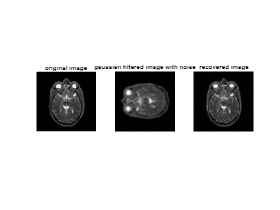

clear all; clc;
Img = imread("Lab 8_data\S2_Q3_utils\t2.jpg");
fisrt_slide = Img(:,:,1);
img = double(fisrt_slide);
% Resize the image to 64x64
img = imresize(img, [64, 64]);
num_row = size(img,1);
num_col = size(img,2);

h = [0,1,0;1,2,1;0,1,0];
K = zeros(size(img));
K(1:3,1:3) = h;

D = zeros(num_col*num_col,num_col*num_col); 

for r = 1:num_row
    for c = 1:num_col

        shiffted_kernel = circshift(K,r-1,1);
        shiffted_kernel = circshift(shiffted_kernel,c-1,2);
        D((r-1)*num_col+c,:) = shiffted_kernel(:);
    end
end

g = D*img(:);
g = g/max(g);
g = g + normrnd(0,0.005,size(g));


learningRate = 0.01; % Learning rate for gradient descent
numIterations = 100; % Number of iterations

% Gradient Descent Loop
f = zeros(size(g));
for iter = 1:numIterations
    % Compute gradient (simplified)
    gradient = g - D*f;
    f = f + learningRate * (D') * (gradient);
    %f = min(max(f, 0), 1);
end

f = f/max(f);
f = reshape(f, num_col, num_col);



figure;
subplot(1,3,1);
imshow(img/max(img(:)))
title('original image')
subplot(1,3,2);
noisy_image  = reshape(g,num_col,num_col);
noisy_image = noisy_image/max(noisy_image(:));
imshow(noisy_image);
title('gaussian filtered image with noise')
subplot(1,3,3);
imshow(f);
title('recovered image')

## Question 5

Anisotropic diffusion, also known as Perona-Malik diffusion, is a nonlinear image processing technique used primarily for noise reduction while preserving important features such as edges. This method operates on the principle of smoothing images in a manner that depends on the local structure of the image, allowing it to effectively reduce noise without overly blurring edges.

## How Anisotropic Diffusion Works

## Basic Principles

- Diffusion Process: Anisotropic diffusion modifies the traditional diffusion process by allowing the diffusion rate to vary based on the local image content. In regions where there are significant gradients (i.e., edges), the diffusion is reduced, preserving these features.

- Gradient-Based Control: The method uses the gradient of the image to determine how much smoothing should occur. If the gradient magnitude is small (indicating a homogeneous area), more smoothing is applied. Conversely, if the gradient is large (indicating an edge), less or no smoothing occurs.

## Mathematical Formulation

The anisotropic diffusion process can be described by the following partial differential equation:


$$\frac{\partial I}{\partial t}=\textrm{div}\left(C\left(||\nabla I||\right)\nabla I\right)$$


∂I∂t=div(C(∥∇I∥)∇I)∂*t*∂*I*�=div(*C*(∥∇*I*∥)∇*I*)

Where:

- $I$ is the image intensity.

- $t$ represents time.

- $\nabla I$ is the gradient of the image.

- $C\left(\parallel \nabla I\parallel \right)$ is a conductance function that controls the diffusion based on the gradient magnitude. Typically, this function decreases as the gradient increases, which means that areas with high gradients (edges) will diffuse less.

## Conductance Function

Common choices for the conductance function include:

- Exponential: $C\left(g\right)=e^{-{\left(\frac{g}{k}\right)}^2 }$

- Inverse: $C\left(g\right)=\frac{1}{1+{\left(\frac{g}{k}\right)}^2 }$�

Here, g is the gradient magnitude and k*k* is a threshold parameter that determines sensitivity to edges.

function kernel = gaussianKernel(size, sigma)
    % Create a meshgrid for the kernel
    [x, y] = meshgrid(-floor(size/2):floor(size/2), -floor(size/2):floor(size/2));
    
    % Calculate the Gaussian kernel
    kernel = exp(-(x.^2 + y.^2) / (2 * sigma^2));
    
    % Normalize the kernel to ensure the sum is 1
    kernel = kernel / sum(kernel(:));
end